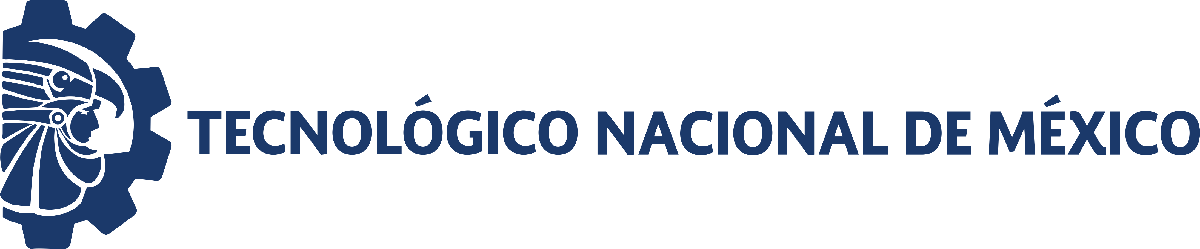                                 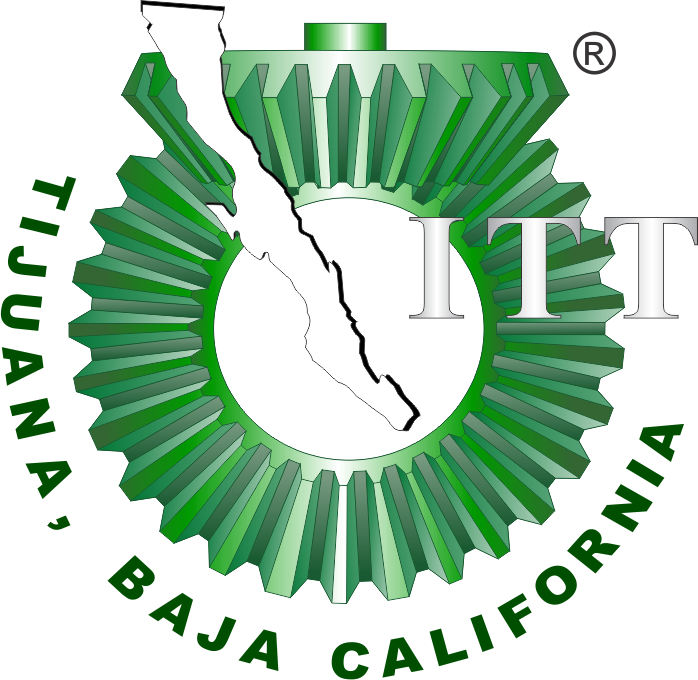

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemas12';
open_system(file);
parameters.StopTime = tend;
parameter.Solver = 'ode45';
parameter.Maxstep = '1E-3';

## Respuesta al escalón

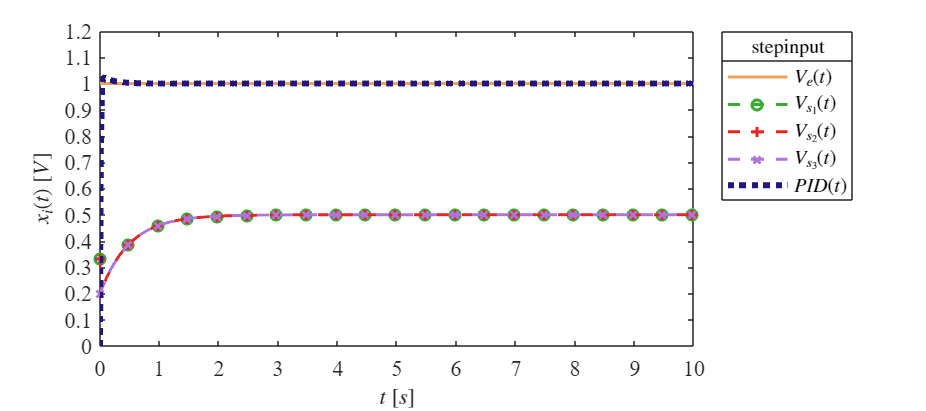

signal = 'step';
set_param('sistemas12/S1','sw','1');
set_param('sistemas12/Ve(t)','sw','1');
x1= sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs1,x1.Vs2,x1.Vs3,x1.PID,signal);

## Respuesta al impulso

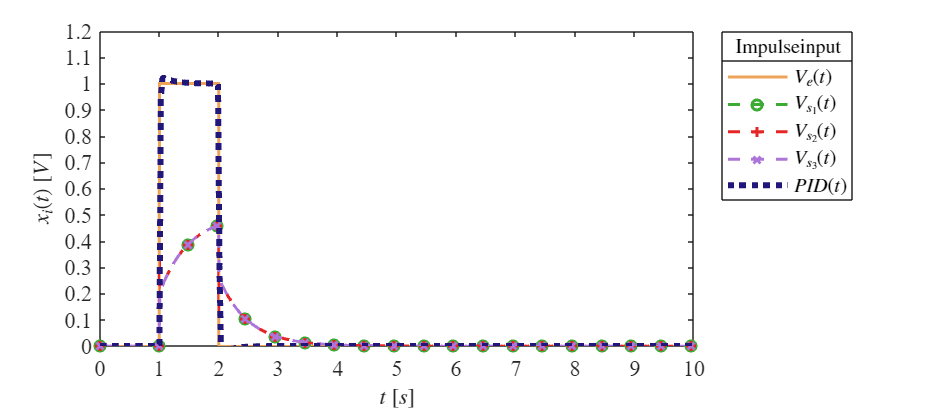

signal = 'Impulse';
set_param('sistemas12/S1','sw','0');
set_param('sistemas12/Ve(t)','sw','1');
x2= sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs1,x2.Vs2,x2.Vs3,x2.PID,signal);

## Respuesta a la rampa

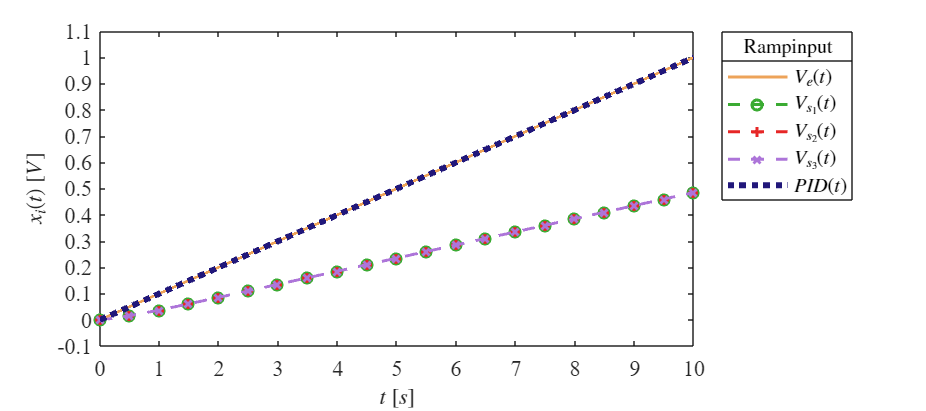

signal = 'Ramp';
set_param('sistemas12/S2','sw','1');
set_param('sistemas12/Ve(t)','sw','0');
x3= sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs1,x3.Vs2,x3.Vs3,x3.PID,signal);

## Respuesta a la función sinusoidal

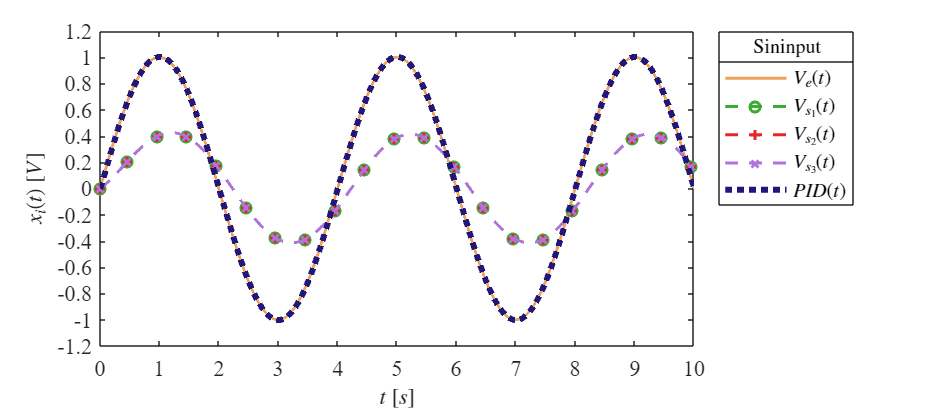

signal = 'Sin';
set_param('sistemas12/S2','sw','0');
set_param('sistemas12/Ve(t)','sw','0');
x4= sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs1,x4.Vs2,x4.Vs3,x4.PID,signal);

## Funcion: Respuesta a las señales

function plotsignals(t,Ve,Vs1,Vs2,Vs3,PID,Signal)
set(figure(),'color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.93,0.64,0.35;
            0.23,0.67,0.20;
            0.90,0.15,0.15;
            0.68,0.46,0.85;
            0.13,0.09,0.48;
            1.00,0.29,0.76];
colororder(mycolors)

    p = plot(t,Ve,'-',t,Vs1,'--o',t,Vs2,'--+',t,Vs3,'--x',t,PID,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'lineWidth',3);
    L= legend('$V_e(t)$','$V_{s_1}(t)$','$V_{s_2}(t)$','$V_{s_3}(t)$','$PID(t)$');
    set(L,'interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,'input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','latex','FontSize',11)

     xlim([0,10]); xticks(0:1:10);
    if Signal == "step" || Signal == "Impulse"
        ylim([0,1.2]); yticks(0:0.1:1.2);
    elseif Signal == "Ramp"
         ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    elseif Signal == "Sin"
         ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2);
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end
